## **Part 1 : System Identification**

You are given a virtual plant as a Simscape model. The input to the plant is voltage from the controller, and the outputs from the plant are angular position  and angular velocity.

Write a thorough, yet concise report on methods of identify the following properties and characteristics

- Open-loop Poles/Zeros

- Transfer Function(s)

- State-space Model

- Settling time and Percent Overshoot

### Author

- Kantaka    Sirithanarattanakul    ID : 62340500002

- Keedita     Chaihetphon              ID : 62340500003

- Pakapak   Silpapinun                  ID : 62340500042

**Date **: 24 June 2021

In order to complete those tasks, the equations describing virtual plants bahavior are used for analysis purpose.

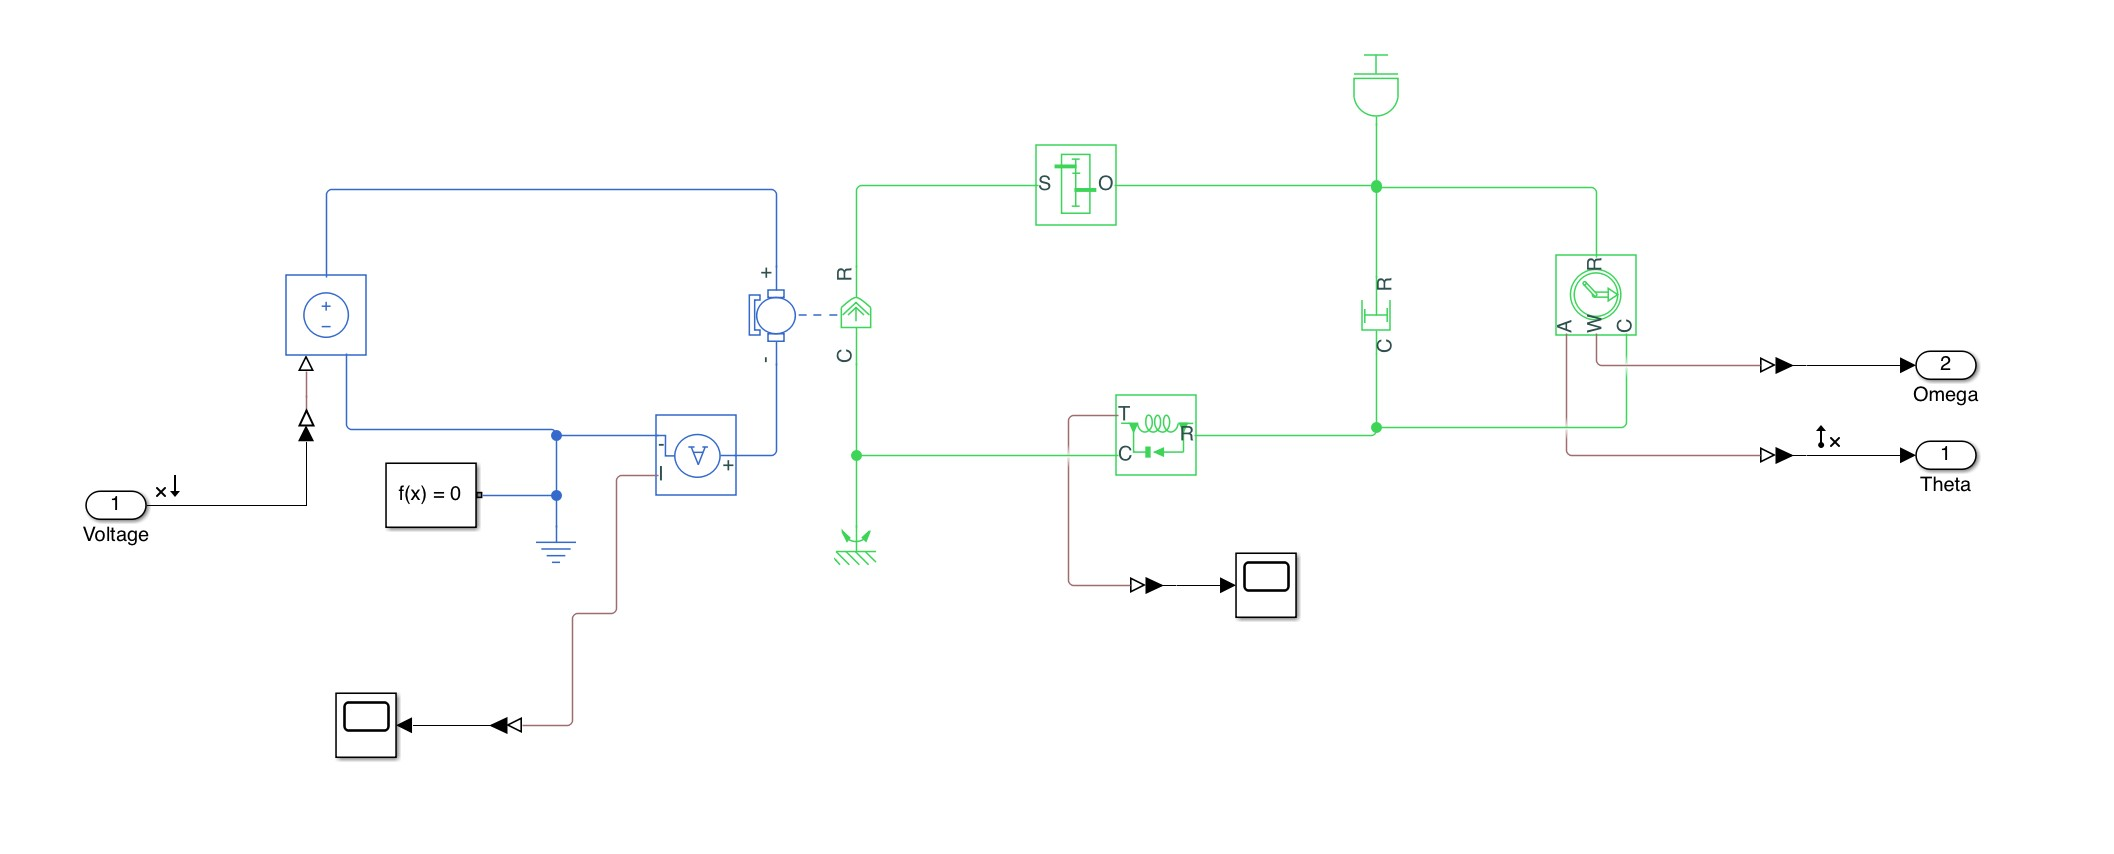

Figure 1: virtual plant

      According to the lesson we had learnt, the electrical system and mechanical system of this virtual plant can be described by following equations respectively,

Electrical system's equation :


$$V_{\textrm{in}} \left(t\right)=R\cdot i\;+L$$

$$\frac{\mathrm{d}}{\mathrm{d}t}i+K_b \;\omega_{\textrm{in}}$$


Laplace transform of electrical system's equation :


$$V_{\textrm{in}} \left(s\right)=\left(R+\textrm{Ls}\right)I\left(s\right)+K_b \;\Omega_{\textrm{in}} \left(s\right)$$


Mechanical system's equation :


$$J_m \dot{{\;\;\omega }_{\textrm{in}} } =K_m \;i-B_m \;\omega_{\textrm{in}} -T_{\textrm{in}}$$


Gearbox :


$$\eta =\frac{T_{\textrm{out}} }{T_{\textrm{in}} }=\frac{\Omega_{\textrm{in}} }{\Omega_{\textrm{out}} }$$


After gearbox :


$$\dot{{J_c \;\omega }_{\textrm{out}} } =T_{\textrm{out}} -B_c \;\omega_{\textrm{out}}$$


Thus, the mechanical system after gearbox's equation is


$$J_m \dot{\eta {\;\;\omega }_{\textrm{out}} } =K_m \;i-B_m \;{\eta \;\omega }_{\textrm{out}} -\frac{1}{\eta }\left(\dot{J_c {\;\;\omega }_{\textrm{out}} } +B_c \omega_{\textrm{out}} \right)$$


Laplace transform of mechanical system after gearbox's equation :


$$\left(J_m \eta +\frac{J_c }{\eta }\right)s\;\Omega \left(s\right)=K_m i-\left(B_m \eta +\frac{B_c }{\eta }\right)\Omega \left(s\right)$$


When,


$$\begin{array}{l}
R:\textrm{Resistance}\;\left(\Omega \right)\\
L:\textrm{Inductance}\;\left(H\right)\\
i:\textrm{Current}\;\left(A\right)\\
\omega_{\textrm{in}} :\textrm{Rotor}\;\textrm{velocity}\;\left(\textrm{rad}/s\right)\\
T_{\textrm{in}} :\textrm{Rotor}\;\textrm{torque}\;\left(N\cdot m\right)\\
K_b :\textrm{Back}\;\textrm{emf}\;\textrm{constant}\\
K_m :\textrm{Motor}\;\textrm{torque}\;\textrm{constant}\\
J_m :\textrm{Rotor}\;\textrm{inertia}\;\left(\textrm{kg}\cdot m^2 \right)\\
B_m :\textrm{Rotor}\;\textrm{damping}\;\left(N\cdot m/\left(\textrm{rad}/s\right)\right)\\
\eta :\textrm{Gear}\;\textrm{ratio}\\
J_c :\textrm{Load}\;\textrm{inetia}\;\left(\textrm{kg}\cdot m^2 \right)\\
B_c :\textrm{Load}\;\textrm{damping}\;\left(N\cdot m/\left(\textrm{rad}/s\right)\right)
\end{array}$$


### **Transfer Function**

From those equations, we can rearrange into transfer function form.


$$T\left(s\right)\;=\;\frac{\Omega_{\textrm{out}} \left(s\right)}{V_{\textrm{in}} \left(s\right)}\;=\;\frac{K_m }{\left(J_m \eta L+\frac{J_c L}{\eta }\right)s^2 +\left(J_m \eta R+B_m \eta L+\frac{J_c R+B_c L}{\eta }\right)s+\left(B_m \eta R+\frac{B_c R}{\eta }+{K_m K}_b \eta \right)}$$


To identify the parameters, the information from DC motor properties are used. Therefore, some parameters can be filled,


$$\begin{array}{l}
L:65\;\left(\mu H\right)\\
J_m :1\;\left(n\cdot \textrm{kg}/m^2 \right)\\
J_c \;:0\ldotp 1\;\left(\textrm{kg}/m^2 \right)\\
B_c :0\ldotp 01\;\left(N\cdot m/\left(\textrm{rad}/s\right)\right)\\
i_{\textrm{NL}} :0\ldotp 075\;\left(A\right)\\
\omega_{\textrm{NL}} :8100\;\left(\textrm{rpm}\right)=8100\cdot \frac{2\pi }{60}=270\pi \left(\textrm{rad}/s\right)\\
V_{\textrm{in}} :12\;\left(V\right)\\
\eta :64\\
P_r :17\;\left(W\right)\\
\omega_r :7700\;\left(\textrm{rpm}\right)
\end{array}$$


To find those missing parameters, motor's conditions are applied into the equations. From the electrical system's equation and mechanical system before gearbox equations are


$$V_{\textrm{in}\;} =R\;i+L\;\frac{d}{\mathrm{d}t}i+K_{b\;} \omega_{\textrm{in}}$$



$$J_m \dot{\omega_{\textrm{in}} } =K_m i-B_m \omega_{\textrm{in}} -T_{\textrm{in}}$$


#### **No-load condition**

    We substitute $V_{\textrm{in}\;} ,\omega_{\textrm{NL}} ,i_{\textrm{NL}} ,\dot{{\;\omega }_{\textrm{out}} } =0,\frac{d}{\textrm{dt}}i=0,{\;J}_m ,\;\textrm{and}\;T_{\textrm{in}} =0$ (no-load condition) into the equations. Therefore,

  
$$12=R\;i+{L\left(0\right)+\;K}_b \;\omega_{\textrm{NL}}$$



$$12=0\ldotp 075\cdot R+K_b \left(8100\cdot \;\frac{2\;\pi \;}{60}\right)-\left(1\right)$$



$$J_m \left(0\right)=K_{m\;} i-B_m \omega_{\textrm{NL}} -0$$



$$K_m i=B_m \omega_{\textrm{NL}}$$



$$K_m \;\left(0\ldotp 075\right)=B_m \left(270\pi \right)-\left(2\right)$$


#### **Steady-state condition**

    In this steady-state condition we assume that it occurs when the plant works with maximum power,

From


$$P=T\omega$$



$$P_r =T_{r\;} \omega_r$$


    We substitute $P_r \;\textrm{and}\;\omega_r$into the equation, such that


$$T_r =\frac{17}{7700}\cdot \frac{60}{2\pi }$$


    After that we substitute the rest of known parameters,$\;\omega_r ,T_r ,\dot{{\;\omega }_{\textrm{out}} } =0,\frac{d}{\textrm{dt}}i=0,{\textrm{and}\;\;J}_m \;$ into the equations as we mentioned. Thus,

Electrical system's equation :


$$\begin{array}{l}
12=R\;i_r +{L\left(0\right)+\;K}_b \;\omega_r \\
12=K_m \;\left(\frac{7700\cdot 2\pi }{60}\right)+R\;i-\left(3\right)
\end{array}$$


Mechanical system after gearbox's equation :


$$\begin{array}{l}
J_m \dot{\omega_{\textrm{in}} } =K_m i-B_m \omega_{\textrm{in}} -T_{\textrm{in}} \\
0=K_m i-B_m \omega_r -T_r \\
\frac{17\cdot \;60}{7700\cdot 2\pi }=K_m \;i-B_m \cdot \left(\frac{7700\cdot 2\pi }{60}\right)-\left(4\right)
\end{array}$$


From equation (2), we substitute $B_m =\frac{K_m }{\left(3600\pi \right)}$. Therefore,


$$i=\left\lbrack \left(\frac{17\cdot 60}{7700\cdot 2\pi }\right)+K_m \cdot \left(\frac{77}{60\cdot 18}\right)\right\rbrack \cdot \frac{1}{K_m }-\left(5\right)$$


Moreover, we assume that the motor in this virtual plant is the ideal motor, such that $K_b =K_m$. From those 5 equations, we use wolfram alpha to find the value of $K_b \;,K_m$,$B_m$,$i$and $R$ as follow,


$$\begin{array}{l}
K_{b\;} \approx 0\ldotp 014112\\
K_{m\;} \approx 0\ldotp 014112\\
B_m \approx 1\ldotp 24778\cdot {10}^{-6} \\
i\approx 1\ldotp 56526\\
R\approx 0\ldotp 396658
\end{array}$$


format long
syms Km Kb Jm Jc Bm Bc nm L R

% Ajarn's physical parameters
Km  = 0.014112;
Kb  = Km;
Jm  = 0.01e-7;
Jc  = 0.1;
Bm  = 1.24778e-6;
Bc  = 0.01;
nm  = 64;
L   = 65e-6;
R   = 0.396658;

% Calculation
K   = Km;
A   = Jm*nm*L + Jc*L/nm;
B   = Jm*nm*R + Bm*nm*L + (Jc*R + Bc*L)/nm;
C   = Bm*nm*R + Bc*R/nm + Km*Kb*nm;

% Transfer function by calculation
TF_Omega_Calculation = tf(K/A, [1 B/A C/A])

We got transfer function of voltage as the input and angular velocity as the output :


$$T\left(s\right)\;=\;\frac{\Omega \left(s\right)}{V_{\textrm{in}} \left(s\right)}\;=\;\frac{1\ldotp 389\cdot {10}^5 }{s^2 +6103s+1\ldotp 264\cdot {10}^5 }$$


and transfer function of voltage as the input and angular position as the output :


$$\Omega \left(s\right)\;=\;s\cdot \Theta \left(s\right)$$



$$\frac{\Theta \left(s\right)}{V_{\textrm{in}} \left(s\right)}\;=\;\frac{1\ldotp 389\cdot {10}^5 }{s^3 +6103s^2 +\left(1\ldotp 264\cdot {10}^5 \right)s}$$


To re-check the answer, we compare the output between calculated transfer function and plant as in the figure 2

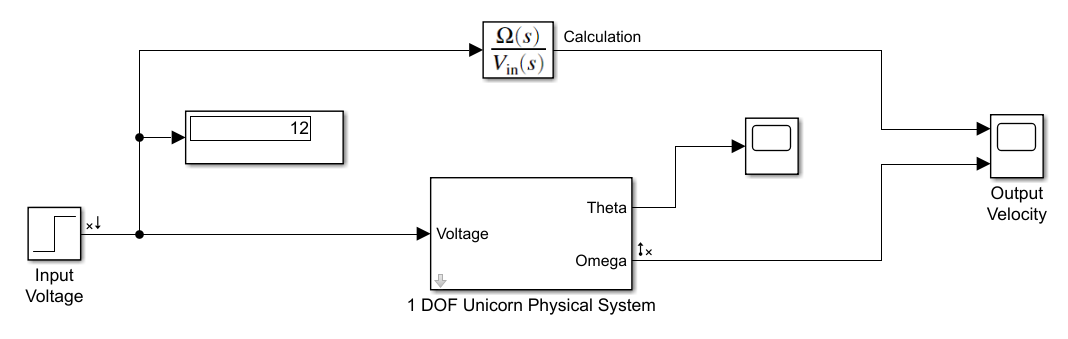

Figure 2: the block diagram of plant and transfer function

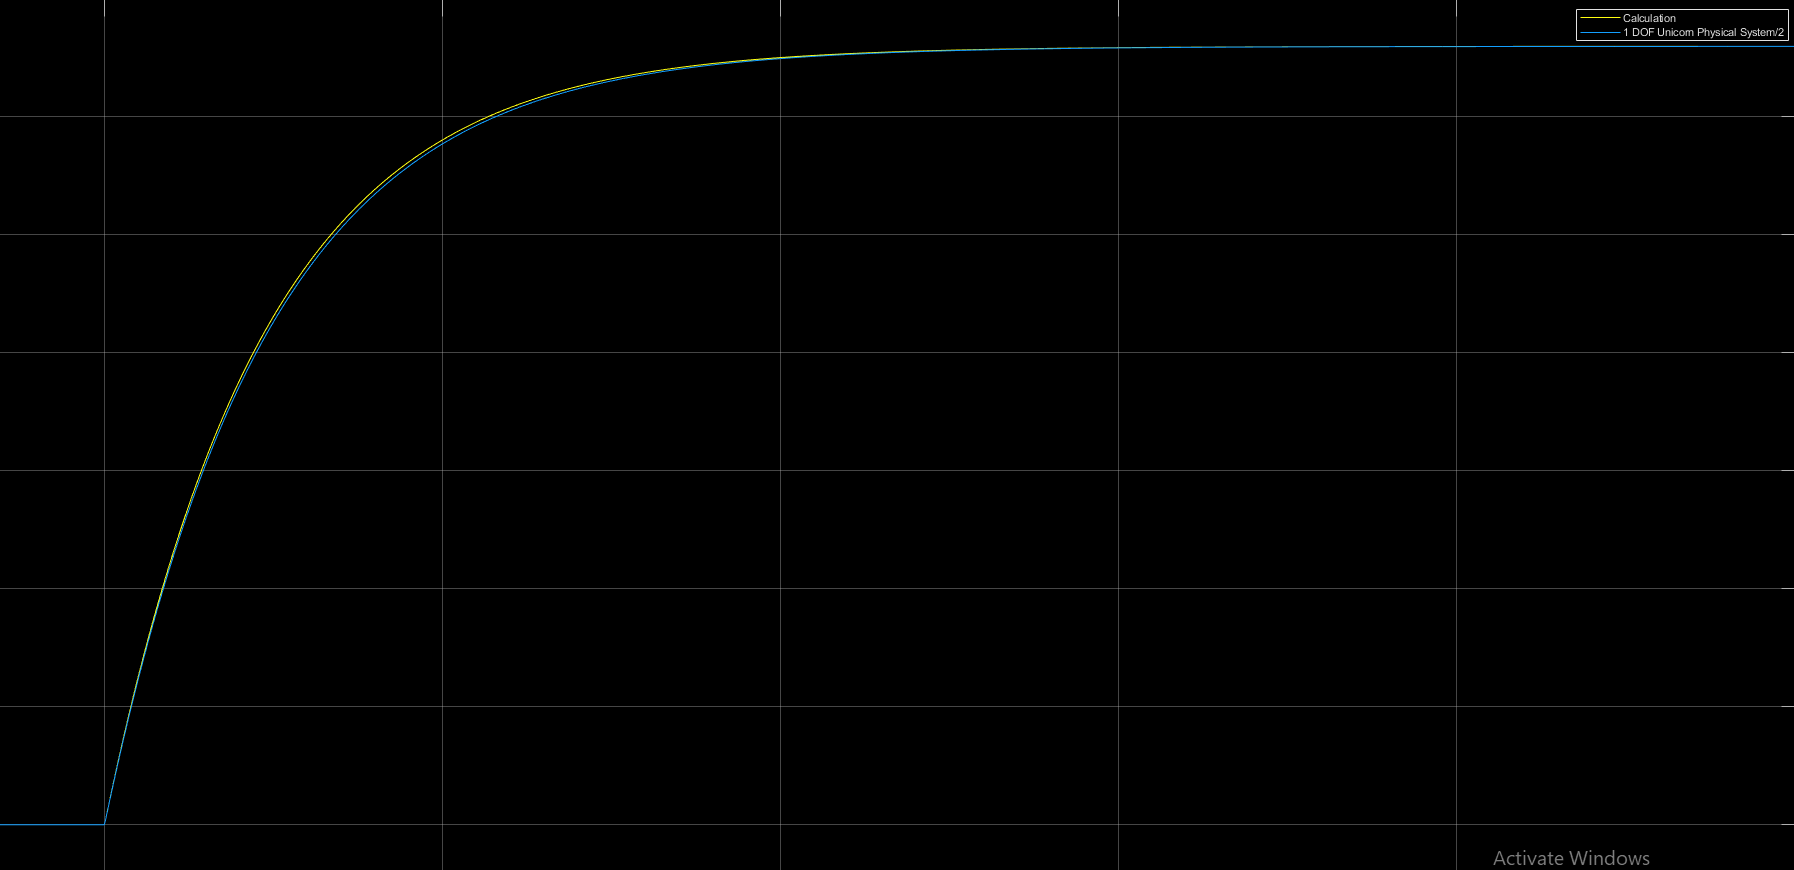

Figure 3: the result from the comparision

From the figure 3, we can conclude that the calculated transfer function is accurate and reliable. 

### Poles and zeroes

After we got the transfer function we calculate its poles and zeros. The result is calculated from wolfram alpha as the following,

Transfer function of voltage as the input and angular velocity as the output :


$$\begin{array}{l}
T\left(s\right)\;=\;\frac{\Omega \left(s\right)}{V_{\textrm{in}} \left(s\right)}\;=\;\frac{1\ldotp 389\cdot {10}^5 }{s^2 +6103s+1\ldotp 264\cdot {10}^5 }\\
T\left(s\right)=\frac{1\ldotp 389\cdot {10}^5 }{\left(s+20\ldotp 7189\right)\left(s+6082\ldotp 22\right)}
\end{array}$$



$$\begin{array}{l}
\textrm{poles}=0\\
\textrm{zeros}=20\ldotp 7819,\;6082\ldotp 22
\end{array}$$


Transfer function of voltage as the input and angular position as the output :


$$\begin{array}{l}
T\left(s\right)=\frac{\Theta \left(s\right)}{V_{\textrm{in}} \left(s\right)}\;=\;\frac{1\ldotp 389\cdot {10}^5 }{s^3 +6103s^2 +\left(1\ldotp 264\cdot {10}^5 \right)s}\\
T\left(s\right)=\frac{1\ldotp 389\cdot {10}^5 }{\left(s+20\ldotp 7189\right)\left(s+6082\ldotp 22\right)s}
\end{array}$$



$$\begin{array}{l}
\textrm{poles}=0\\
\textrm{zeros}=0,\;20\ldotp 7819,\;6082\ldotp 22
\end{array}$$


To re-check the answer, we use the Pole-Zero Map from Model linearizer in Simulink as in Figure 4.

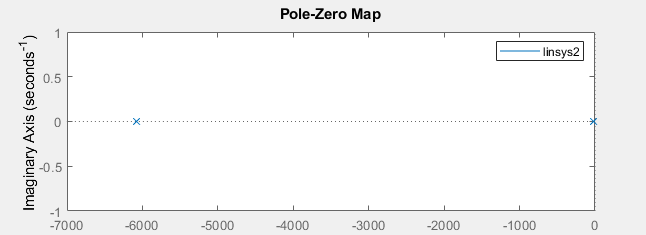

Figure 4: Pole-Zero Map from Model linearizer in Simulink

### Settling Time and Percent Overshoot

To identify the settling time and percent overshoot, scope is used. According to what we had learnt, the settling time is the used time reaching plus or minus 2% of the final value.

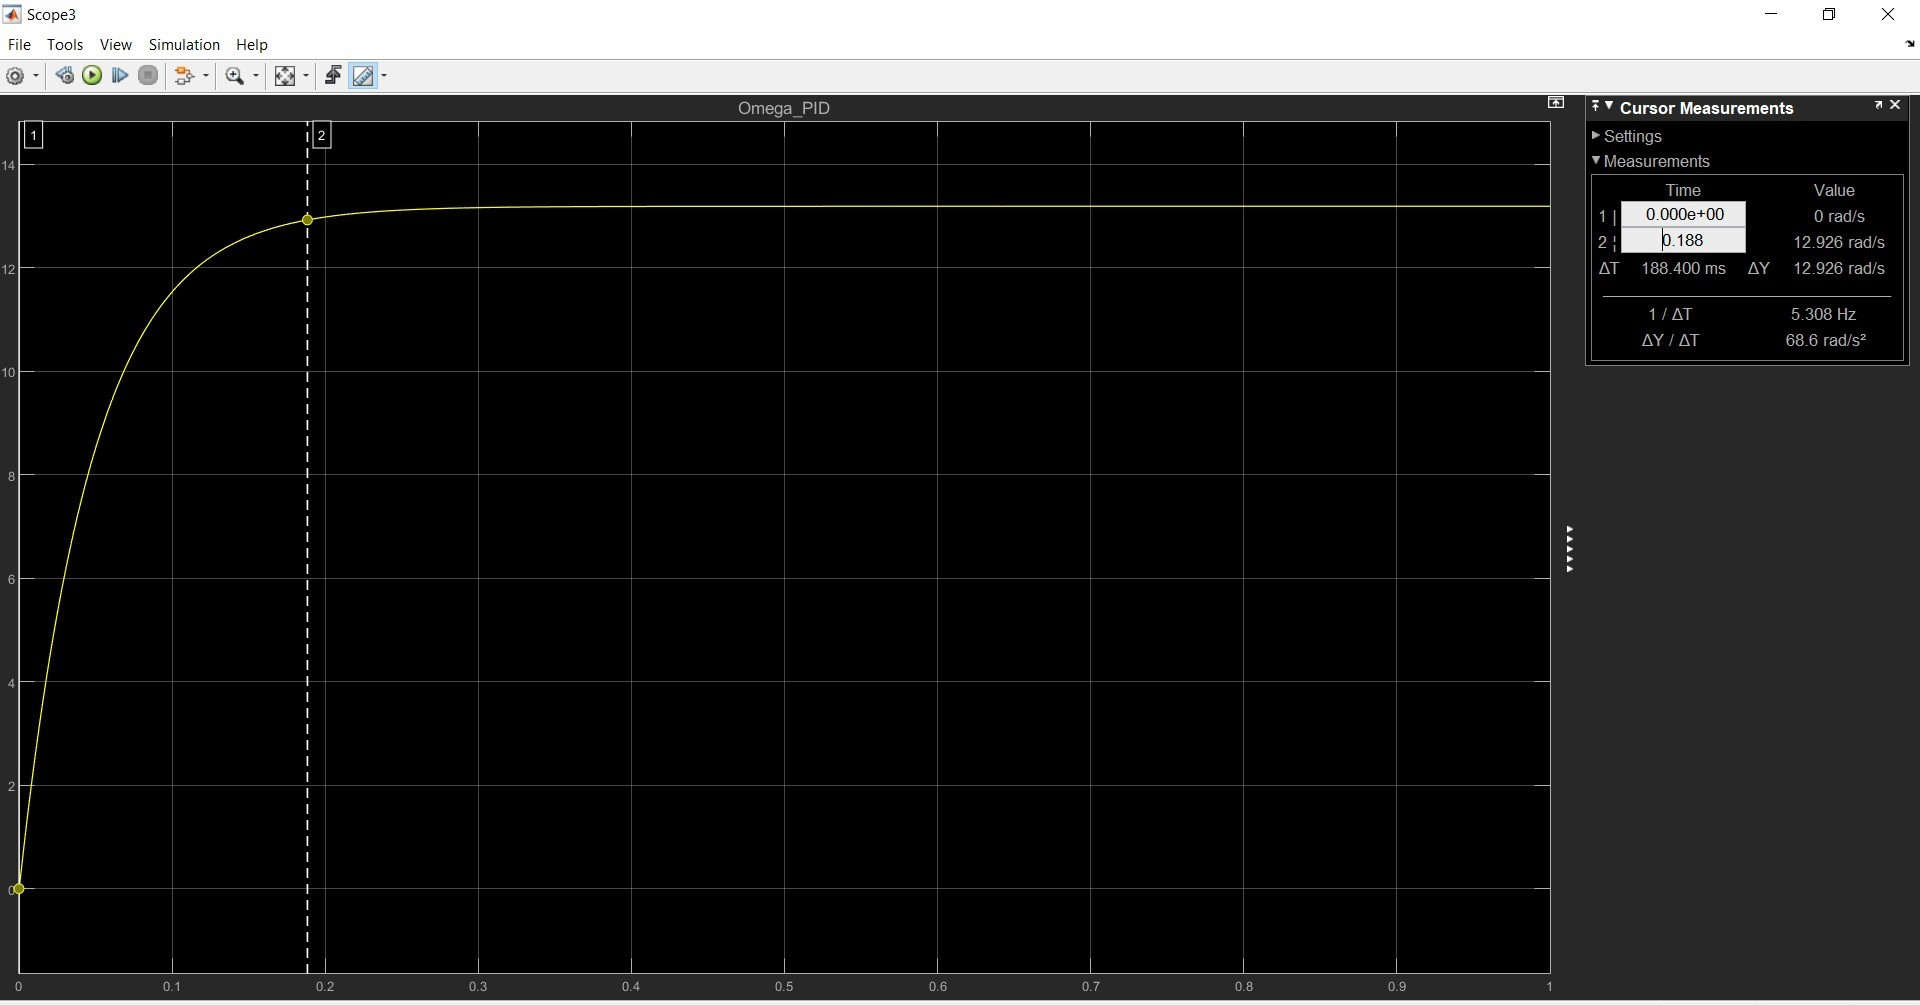

Figure 5: Scope in simulink used for finding settling time

    From the figure 5, the settling time of this plant is 0.188 sec. Furthermore, as you see in the figure, there is no overshoot. Therefore, the percent overshoot is 0.

### State Space Modelling

To identify the state space we use the electrical system's equation and mechanical system's equation and rearrange as following,

Electrical system's equation :


$$\begin{array}{l}
V_{\textrm{in}} =R\;i-L\frac{\mathrm{d}}{\mathrm{d}t}i+K_b \omega_{\textrm{in}} \\
\frac{\mathrm{d}}{\mathrm{d}t}i=\frac{R}{L}i+\frac{K_b }{L}\omega_{\textrm{in}} -\frac{V_{\textrm{in}} }{L}
\end{array}$$


Mechanical system's equation :


$$\begin{array}{l}
\left(J_m \eta +\frac{J_c }{\eta }\right)\frac{d}{\mathrm{d}t}\omega_{\textrm{out}} =K_m i-\left(B_m \eta +\frac{B_c }{\eta }\right)\omega_{\textrm{out}} \\
\frac{d}{\mathrm{d}t}\omega_{\textrm{in}} =\frac{K_m }{\left(J_m \eta +\frac{J_c }{\eta }\right)\cdot \eta }i-\frac{\left(B_m \eta +\frac{B_c }{\eta }\right)}{\left(J_m \eta +\frac{J_c }{\eta }\right)}\omega_{\textrm{in}} \\
\omega_{\textrm{out}\;} =\frac{\omega_{\textrm{in}} }{64}\\
\frac{d}{\mathrm{d}t}\omega_{\textrm{out}} =\frac{1}{64}\cdot \left(\frac{d}{\mathrm{d}t}\omega_{\textrm{in}} \right)
\end{array}$$


From those rearranged equations, we can identify state of the system, $\overrightarrow{\;x}$, which is 


$$\overrightarrow{\;x} =\left\lbrack \begin{array}{c}
i\\
\omega_{\textrm{in}} \\
\theta_{\textrm{out}} 
\end{array}\right\rbrack$$


Therefore, the state space of system will be as following,


$$\dot{\;\overrightarrow{x} } =\left\lbrack \begin{array}{c}
\dot{i} \\
\dot{\;\omega_{\textrm{in}} } \\
\theta_{\textrm{out}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\frac{R}{L} & \frac{K_b }{L} & 0\\
\frac{K_m }{\left(J_m \eta +\frac{J_c }{\eta }\right)\cdot \eta } & \frac{\left(B_m \eta +\frac{B_c }{\eta }\right)}{\left(J_m \eta +\frac{J_c }{\eta }\right)} & 0\\
0 & \frac{1}{64} & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i\\
\omega_{\textrm{in}} \\
\theta_{\textrm{out}} 
\end{array}\right\rbrack +$$

$$\left\lbrack \begin{array}{c}
\frac{1}{L}\\
0\\
0
\end{array}\right\rbrack \cdot V_{\textrm{in}}$$



$$\overrightarrow{y} =\left\lbrack \begin{array}{c}
\omega_{\mathrm{out}} \\
\theta_{\mathrm{out}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & \frac{1}{64} & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i\\
\omega_{\mathrm{in}} \\
\theta_{\mathrm{out}} 
\end{array}\right\rbrack$$


# **(NOT USE)**

so we got the static gain constant :


$$k\;=\;1\ldotp 359\cdot {10}^5$$


and natural frequency :


$$\omega_n \;=\sqrt{1\ldotp 264\cdot {10}^5 }\approx 355\ldotp 528$$


and the damping ratio :


$$\zeta \;=\;\frac{6103}{2\cdot 355\ldotp 527}\approx \;8\ldotp 583$$


% Transfer function by Model Linearizer
tf(Omega_ModelLinearizer)

ans =
 
  From input "Voltage" to output "PS-Simulink Converter":
         1.389e05
  -----------------------
  s^2 + 6103 s + 1.264e05
 
Name: Linearization at model initial condition
Continuous-time transfer function.




% Solve the equations find Km, Kb, R
%====================================================================================================================
%EQN = [K/A == 1.389e05, B/A == 6103, C/A == 1.264e05];
%VAR = [Km, Kb, R];
%[Km_solve, Kb_solve, R_solve] = solve(EQN, VAR);
%vpa(Km_solve, 10)  % got Km = 0.01410760907
%vpa(Kb_solve, 10)  % got Kb = 0.01414337513
%vpa(R_solve, 10)   % got R  = 0.3968878528
%====================================================================================================================

% DC motor default parameters
Km  = 0.014112;
Kb  = Km;
Jm  = 0.01e-7;
Jc  = 0.1;
Bm  = 1.24778e-6;
Bc  = 0.01;
nm  = 64;
L   = 65e-6;
R   = 0.396658;

% Calculation
K   = Km;
A   = Jm*nm*L + Jc*L/nm;
B   = Jm*nm*R + Bm*nm*L + (Jc*R + Bc*L)/nm;
C   = Bm*nm*R + Bc*R/nm + Km*Kb*nm;

% Transfer function by calculation
tf(K/A, [1 B/A C/A])

ans =
 
         1.389e05
  -----------------------
  s^2 + 6103 s + 1.264e05
 
Continuous-time transfer function.



% Transfer function by Model Linearizer
tf(Omega_ModelLinearizer_default)

ans =
 
  From input "Step" to output "Omega":
           3.667e04
  --------------------------
  s^2 + 3.25e05 s + 3.411e04
 
Name: Linearization at model initial condition
Continuous-time transfer function.

